# File for the figures of the paper

The figures presented are based on bayesian statistics calibrated parameters that were performed with the toolbox DREAM. The package is only for private use, and the specific configuration used to run DREAM with the model versions can be provided upon request. The outputs are as well very heavy and available upon request. 

## Figure 2

We present the procedure to calculate the figure 2 of the paper as well as supplementary figure S4. Files for running this figure are available in the file example_parameter_fits. Final editing of the figure was done with the software Inkscape. 

### Calling Simulations for Variant 2

% Calling Data Chemostat %

load('chemostat_data.txt')
EF_C  = -5.36;
sd_C  = 0.2;
Datam = chemostat_data(:,1);
Datas = chemostat_data(:,2);

DAT_C   = vertcat(Datam(1:10),Datam(11:15));
DAT_Csd = vertcat(Datas(1:10),Datas(11:15));

% Calling Data Retentostat %

load('retentostat_data.txt')

DatamR   = retentostat_data(:,1);
DatasR   = retentostat_data(:,2);

DAT_R    = vertcat(DatamR(1:2),DatamR(3));
DAT_Rsd  = vertcat(DatasR(1:2),DatasR(3));
EF_R     = -0.45;
sd_R     = 0.36;

% Parameter %

load('variant_2_accepted.mat')
load('EF_variant_2.mat')


#### Atrazine

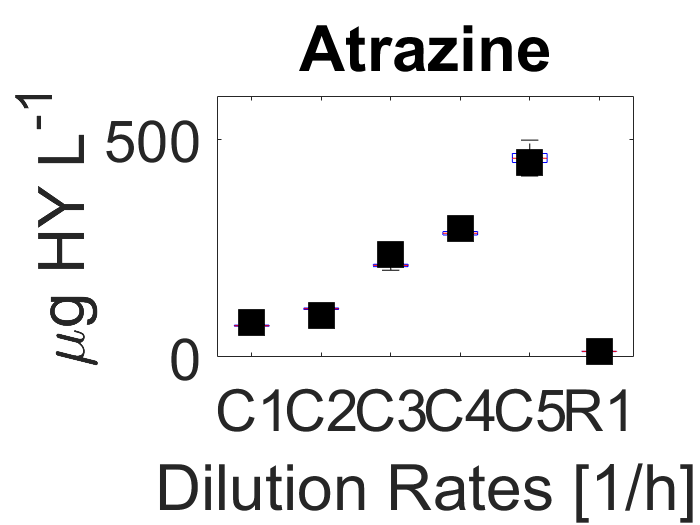

A   = Pars_output(1,:)';
B   = Pars_output(2,:)';
C   = Pars_output(3,:)';
D   = Pars_output(4,:)';
E   = Pars_output(5,:)';
A1r = Pars_output(17,:)';

x = [A; B; C; D; E; A1r];

g1 = repmat({'C1'},187498,1);
g2 = repmat({'C2'},187498,1);
g3 = repmat({'C3'},187498,1);
g4 = repmat({'C4'},187498,1);
g5 = repmat({'C5'},187498,1);
g6 = repmat({'R1'},187498,1);

g = [g1; g2; g3; g4; g5; g6];

% Plotting %

figure
AH = boxplot(x,g,'symbol','');
hold on
B = plot(vertcat(DAT_C(1:5),DAT_R(1)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
ylim([0 6e2])
set(gca,'FontSize',35)
xlabel('Dilution Rates [1/h]')
ylabel('\mug HY L^{-1}')
title('Atrazine')
box on
hold off

#### Hydroxyatrazine

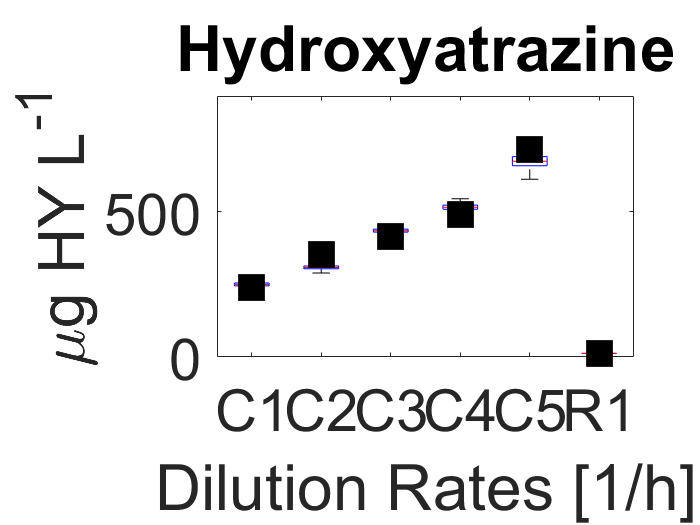

AH  = Pars_output(6,:)';
BH  = Pars_output(7,:)';
CH  = Pars_output(8,:)';
DH  = Pars_output(9,:)';
EH  = Pars_output(10,:)';
A2a = Pars_output(18,:)';

xH = [AH; BH; CH; DH; EH; A2a];

g1H = repmat({'C1'},187498,1);
g2H = repmat({'C2'},187498,1);
g3H = repmat({'C3'},187498,1);
g4H = repmat({'C4'},187498,1);
g5H = repmat({'C5'},187498,1);
g6H = repmat({'R1'},187498,1);

gH= [g1H; g2H; g3H; g4H; g5H; g6H];

% Plotting %

figure
AH = boxplot(xH,gH,'symbol','');
hold on
BH = plot(vertcat(DAT_C(6:10),DAT_R(2)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
xlabel('Dilution Rates [1/h]')
ylabel('\mug HY L^{-1}')
title('Hydroxyatrazine')
ylim([0 9e2])
set(gca,'FontSize',35)
box on
hold off

#### Biomass

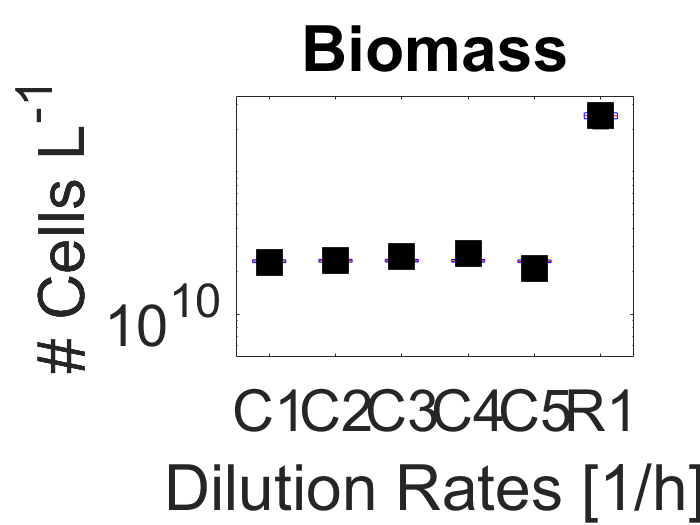

Ac  = Pars_output(11,:)';
Bc  = Pars_output(12,:)';
Cc  = Pars_output(13,:)';
Dc  = Pars_output(14,:)';
Ec  = Pars_output(15,:)';
A3a = Pars_output(19,:)';

xc = [Ac; Bc; Cc; Dc; Ec; A3a];

g1c = repmat({'C1'},187498,1);
g2c = repmat({'C2'},187498,1);
g3c = repmat({'C3'},187498,1);
g4c = repmat({'C4'},187498,1);
g5c = repmat({'C5'},187498,1);
g6c = repmat({'R1'},187498,1);

gc= [g1c; g2c; g3c; g4c; g5c; g6c];

% Plotting %

figure
Ac = boxplot(xc,gc,'symbol','');
hold on
Bc = plot(vertcat(DAT_C(11:15),DAT_R(3)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
xlabel('Dilution Rates [1/h]')
ylabel('# Cells L^{-1}')
title('Biomass')
set(gca,'FontSize',35,'YScale', 'log')
ylim([5e9 inf])
box on
hold off

#### Enrichment Factor

AH  = -1*Pars_output(16,:)';
A2a = -1*Pars_output(20,:)';

BH  = [];
CH  = [];
DH  = [];
EH  = [];

for i = 1:length(DL1)
    BH(end+1) = DL1{i,1}(2);
    CH(end+1) = DL1{i,1}(3);
    DH(end+1) = DL1{i,1}(4);
    EH(end+1) = DL1{i,1}(5);
end

xH = [AH; BH'; CH'; DH'; EH'; A2a];

g1H = repmat({'C1'},187498,1);
g2H = repmat({'C2'},187498,1);
g3H = repmat({'C3'},187498,1);
g4H = repmat({'C4'},187498,1);
g5H = repmat({'C5'},187498,1);
g6H = repmat({'R1'},187498,1);

gH= [g1H; g2H; g3H; g4H; g5H; g6H];

% Plotting %

figure
AH = boxplot(xH,gH,'symbol','');
hold on
% Bc = plot(vertcat(EF_C,EF_C,EF_C,EF_C,EF_C,EF_R),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
xlabel('Dilution Rates [1/h]')
ylabel('Enrichment factor \epsilon')
title('Enrichment factor')
yline(EF_C)

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: -5.3600
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


yline(EF_R)

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: -0.4500
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


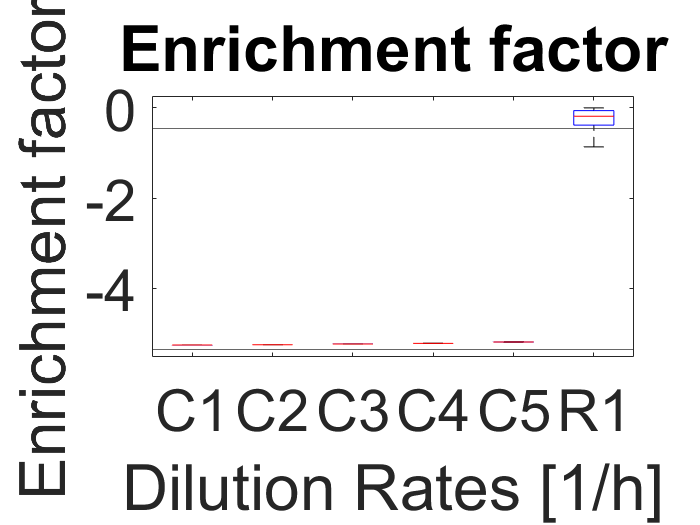

set(gca,'FontSize',35)
box on
hold off

## Figure 4

We present the procedure to calculate the figure 4 of the paper. Files for running this figure are available upon request. Final editing of the figure was done with the software Inkscape. 

### Atrazine residual concentration after 30 years

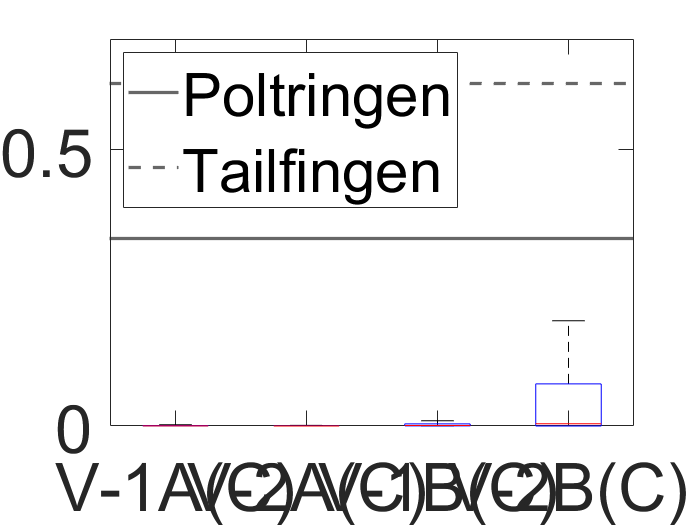

A  = [];
Ar = [];
B  = [];
Br = [];
C  = [];
Cr = [];
D  = [];
Dr = [];

load('variant_1_soil.mat')
for i = 1:length(EF2)
    B(end+1)  = EF2{i,1}(1);
    Br(end+1) = EF2{i,1}(5);
    D(end+1)  = EF2{i,1}(3);
    Dr(end+1) = EF2{i,1}(7);
end
load('variant_2_soil.mat')
for i = 1:length(EF)
    A(end+1)  = EF{i,1}(1);
    Ar(end+1) = EF{i,1}(5);
    C(end+1)  = EF{i,1}(3);
    Cr(end+1) = EF{i,1}(7);
end

PoltringenA = 1e0*0.34;
TailfingenA = 1e0*0.62;

xC    = 1e0*[B';A';D'; C'];
xR    = 1e0*[Br';Ar';Dr';Cr'];

g1s = repmat({'V-1A(C)'},187498,1);
g2s = repmat({'V-1A(R)'},187498,1);
g3s = repmat({'V-2A(C)'},187498,1);
g4s = repmat({'V-2A(R)'},187498,1);
g5s = repmat({'V-1B(C)'},187498,1);
g6s = repmat({'V-1B(R)'},187498,1);
g7s = repmat({'V-2B(C)'},187498,1);
g8s = repmat({'V-2B(R)'},187498,1);

gC  = [g1s;g3s;g5s;g7s];
gR  = [g2s;g4s;g6s;g8s];

%
figure
Ac = boxplot(xC,gC,'symbol','');
hold on
P = yline(PoltringenA,'-','LineWidth',2);
T = yline(TailfingenA,'--','LineWidth',2);
legend([P T],'Poltringen','Tailfingen','Location','northwest')
set(gca,'FontSize',40,'TickLength',[0.030 0.015])
ylim([0 0.7])
box on
hold off

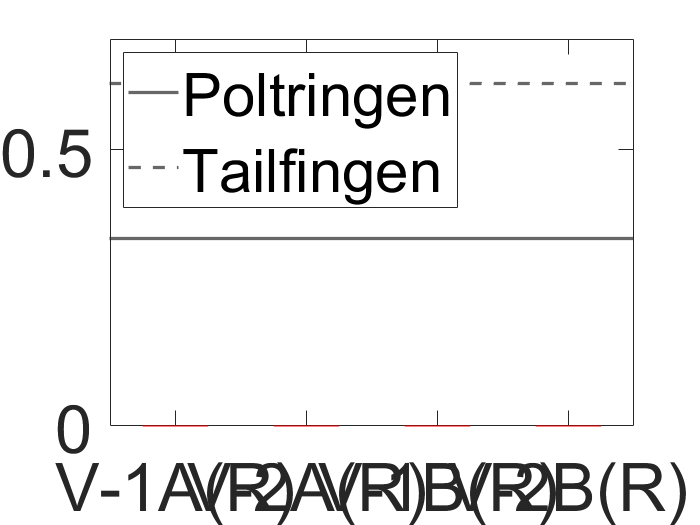

%
figure
Ac = boxplot(xR,gR,'symbol','');
hold on
P = yline(PoltringenA,'-','LineWidth',2);
T = yline(TailfingenA,'--','LineWidth',2);
legend([P T],'Poltringen','Tailfingen','Location','northwest')
set(gca,'FontSize',40,'TickLength',[0.030 0.015])
ylim([0 0.7])
box on
hold off

### Hydroxyatrazine residual concentration after 30 years

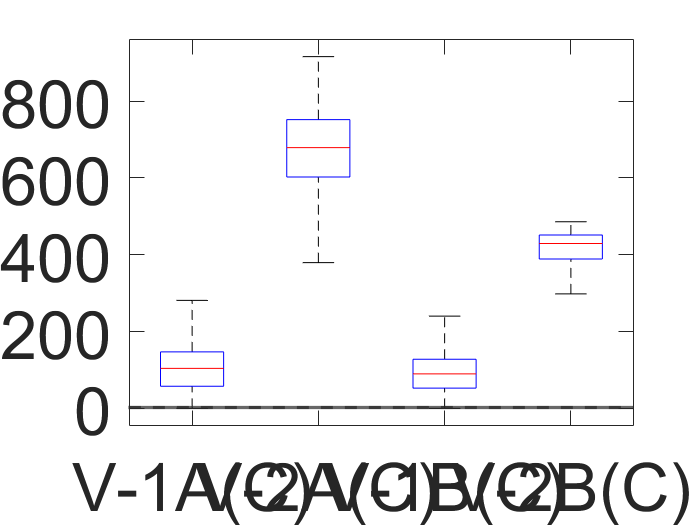

A  = [];
Ar = [];
B  = [];
Br = [];
C  = [];
Cr = [];
D  = [];
Dr = [];

load('variant_1_soil.mat')
for i = 1:length(EF2)
    B(end+1)  = EF2{i,1}(2);
    Br(end+1) = EF2{i,1}(6);
    D(end+1)  = EF2{i,1}(4);
    Dr(end+1) = EF2{i,1}(8);
end
load('variant_2_soil.mat')
for i = 1:length(EF)
    A(end+1)  = EF{i,1}(2);
    Ar(end+1) = EF{i,1}(6);
    C(end+1)  = EF{i,1}(4);
    Cr(end+1) = EF{i,1}(8);
end

PoltringenH = 2.12;
TailfingenH = 1.94;

xC    = 1e0*[B';A';D'; C'];
xR    = 1e0*[Br';Ar';Dr';Cr'];

g1s = repmat({'V-1A(C)'},187498,1);
g2s = repmat({'V-1A(R)'},187498,1);
g3s = repmat({'V-2A(C)'},187498,1);
g4s = repmat({'V-2A(R)'},187498,1);
g5s = repmat({'V-1B(C)'},187498,1);
g6s = repmat({'V-1B(R)'},187498,1);
g7s = repmat({'V-2B(C)'},187498,1);
g8s = repmat({'V-2B(R)'},187498,1);

gC  = [g1s;g3s;g5s;g7s];
gR  = [g2s;g4s;g6s;g8s];

%

figure
Ac = boxplot(xC,gC,'symbol','');
hold on
P = yline(PoltringenH,'-','LineWidth',2);
T = yline(TailfingenH,'--','LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015]) % ,'YScale','log'
% ylim([0 35])
% ylim([10 35])
% ylim([40 inf])
box on
hold off

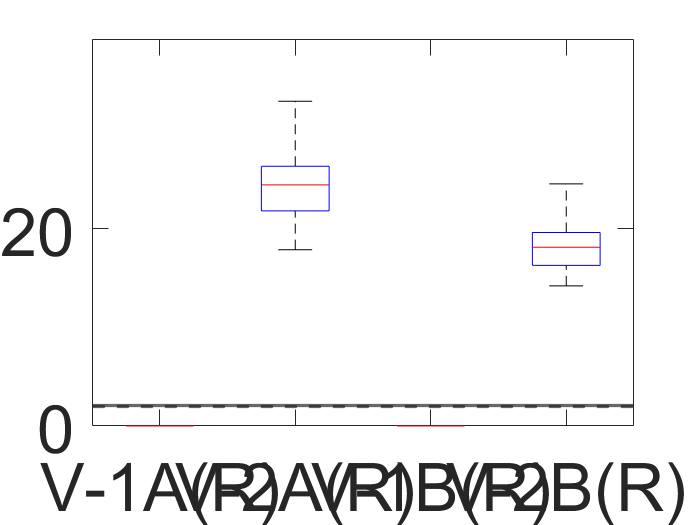


%

figure
Ac = boxplot(xR,gR,'symbol','');
hold on
P = yline(PoltringenH,'-','LineWidth',2);
T = yline(TailfingenH,'--','LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015]) % ,'YScale','log'
ylim([0 inf])
box on
hold off

## Supplementary Figure S1

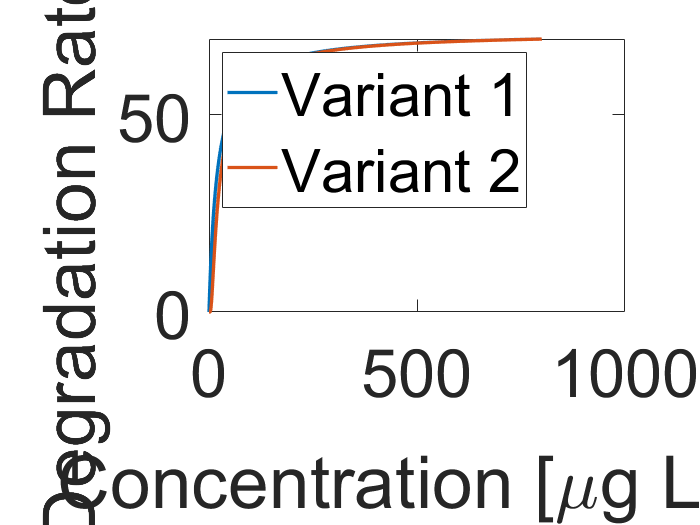

k_m_h = 71;
K_m_h = 20;

C_HYc = linspace(0,800,800);

figure
MonC = plot(C_HYc,k_m_h*C_HYc.*(K_m_h+C_HYc).^(-1),'LineWidth',2);
hold on
therC  = plot(C_HYc,k_m_h.*exp(-K_m_h./C_HYc),'LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015])
legend([MonC therC],'Variant 1','Variant 2','Location','northwest')
xlabel('Concentration [\mug L^{-1}]')
ylabel('Degradation Rate [d^{-1}]')
box on
hold off